% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clc
close all
clear all


figure(1);
hold on;
amers=[3 5 7 9 3 5 7 9;2 2 2 2 5 5 5 5] %la matrice des amers 

amers =      3     5     7     9     3     5     7     9
     2     2     2     2     5     5     5     5


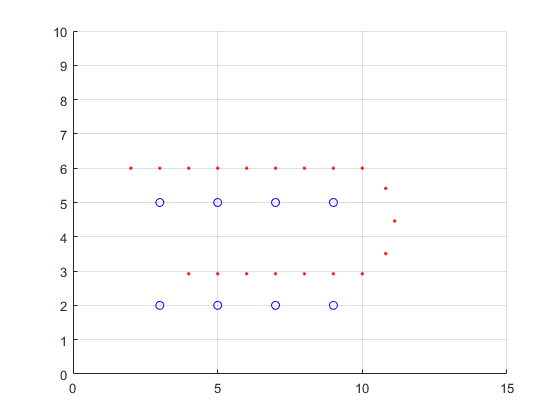

r0=[1;6];   % la position initial du robot à k=0
r=[];
for k=1:length(amers)% affichage des amers
    grid on;
    axis([0 15 0 10])% definir les dimensions de la fenetre daffichage
    plot(amers(1,k),amers(2,k),'ob')
end
r(:,1) = [2;6;0];
ro=0;
for k=1:7
    u(:,k)= [1;0;0];
end
for k=8:12 
    u(:,k)= [1;0;-pi()/5];% angle = pi/(nombre des echantillons)
end
for k=13:20
    u(:,k)= [1;0;0];
end

for k=1:18
    r(:,k+1)=r(:,k) + [u(1,k)*cos(r(3,k)) - u(2,k)*sin(r(3,k));u(1,k)*sin(r(3,k)) + u(2,k)*cos(r(3,k)); u(3,k)];
end
plot(r(1,:),r(2,:),'.r')

r

r =     2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   10.8090   11.1180   10.8090   10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000
    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    5.4122    4.4612    3.5101    2.9223    2.9223    2.9223    2.9223    2.9223    2.9223    2.9223
         0         0         0         0         0         0         0         0   -0.6283   -1.2566   -1.8850   -2.5133   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416



% r(1,1)=2;
% r(2,1)=6;
% u=[0.2;0]
% for k=1:35
%     r(1,k+1) = r(1,k) + u(1,1);
%     r(2,k+1) = r(2,k) + u(2,1);
%     plot(r(1,max(k-1,1):k),r(2,max(k-1,1):k),'.r')
% end
% r1(1,1)=9;
% r1(2,1)=6;
% for k=1:10
%     hold on
%     r1(1,k+1) = r1(1,k) + 0.1;
%     r1(2,k+1) = sqrt(1-(r1(1,k+1)-9)^2) +5;
%     plot(r1(1,:),r1(2,:),'.r')
%     drawnow
% end 
% r2(1,1)=10;
% r2(2,1)=5;
% for k=1:10
%     r2(1,k+1) = r2(1,k) - 0.1;
%     r2(2,k+1) = -sqrt(1-(r2(1,k+1)-9)^2) +5;
%     plot(r2(1,:),r2(2,:),'.r')
%     drawnow
% end 
% r3(1,1)=9;
% r3(2,1)=4;
% u1=[0.2;0]
% for k=1:35
%     r3(1,k+1) = r3(1,k) - u1(1,1);
%     r3(2,k+1) = r3(2,k) - u1(2,1);
%     plot(r3(1,:),r3(2,:),'.r')
%     drawnow
% end


